repo_root = "/Users/zahir/Documents/MATLAB/astra/";
data_root = fullfile(repo_root, "data/");
code_root = "/Users/zahir/Documents/GitHub/astra/";

% currently 82 and 90 -> smallest TV
% also 81
case_nr = "DLDP_090";

%%% Metric of what ASTRA is calculating and perturbation type
% abs_dmax, max, mean, (abs_dmean)     Dilation, Erosion
% pert_type = "Dilation";
pert_type = "Erosion";

metric = 'abs_dmax';
out_metric = "Absolute Max Dose";

gt_target = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/Target.nii.gz"));
gt_brain = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/Brain.nii.gz"));
gt_brainstem = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/Brainstem.nii.gz"));
gt_hippocampusL = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/Hippocampus_L.nii.gz"));
gt_hippocampusR = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/Hippocampus_R.nii.gz"));


ct_data = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/CT.nii.gz"));
brain_size = nnz(gt_brain);
tumor_size = nnz(gt_target);
brainstem_size = nnz(gt_brainstem);
hippocampusL_size = nnz(gt_hippocampusL);
hippocampusR_size = nnz(gt_hippocampusR);


groundtruthConfig = load(fullfile(code_root, "astra", "visualization", "groundtruthConfig.mat"));
sceneConfig = load(fullfile(code_root, "astra", "visualization", "sceneConfig.mat"));
heatmapConfig = load(fullfile(code_root, "astra", "visualization", "heatmapConfig2.mat"));
heatmapConfigT = load(fullfile(code_root, "astra", "visualization", "heatmapConfig2.mat"));
objectConfigJet = load(fullfile(code_root, "astra", "visualization", "objectConfigJet.mat"));
objectConfigJetV2 = load(fullfile(code_root, "astra", "visualization", "objectConfigJetV2.mat"));

max_ct = max(ct_data(:));
ct_data(1, :, :) = max_ct;
ct_data(:, 1, :) = max_ct;
ct_data(:, :, 1) = max_ct;
ct_data(128, :, :) = max_ct;
ct_data(:, 128, :) = max_ct;
ct_data(:, :, 128) = max_ct;

%vol = volshow(ct_data, RenderingStyle="SlicePlanes");
%vol.SlicePlaneValues = [-1 0 0 97; 0 -1 0 68; 0 0 -1 2];

props = regionprops3(gt_target, "Centroid");
sceneConfig.sceneConfig.CameraTarget = props.Centroid;
sceneConfig.sceneConfig.BackgroundColor = [0, 0, 0];
sceneConfig.sceneConfig.Lighting = 0;

groundtruthConfig.groundtruthConfig.Colormap = [0.980, 0.298, 0.337];
vol = volshow(gt_target, groundtruthConfig.groundtruthConfig); %, "Parent", vol.Parent);
scenePropsT = fields(sceneConfig.sceneConfig);
for prop_idx = 1:length(scenePropsT)
    vol.Parent.(scenePropsT{prop_idx}) = sceneConfig.sceneConfig.(scenePropsT{prop_idx});
end

oar_list = ["Brainstem", "Hippocampus_L", "Hippocampus_R"]; % , "Eye_L", "Eye_R"]
target = "Target";

%%% Choose folder of Dilation or Erosion
p_tv = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Perturbed_" + target + ".nii.gz"));

p_T_HR = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Perturbed_THippocampus_R" + ".nii.gz"));
p_T_HL = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Perturbed_THippocampus_L" + ".nii.gz"));
p_T_BS = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Perturbed_TBrainStem" + ".nii.gz"));
% p_T_ER = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Perturbed_TEye_R" + ".nii.gz"));
% p_T_EL = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Perturbed_TEye_L" + ".nii.gz"));

pred_tv = niftiread(fullfile(data_root, "Prediction/" + pert_type + "/" + case_nr + "/Prediction_NoPert" + target + ".nii.gz"));


%%% Change here!!!
%%% p_tv, p_T_HR, p_T_HL, p_T_BS (p_T_ER, p_T_EL)
%%% Hippocampus Right, Hippocampus Left, Brainstem

% curr_org_str = "Abs delta max of perturbed TV " + case_nr;
curr_org_str = "Perturbed TV with delta max of Hippocampus Right " + case_nr;
% curr_org_str = "Perturbed TV with delta max of Brainstem " + case_nr;

curr_org = p_T_BS;
curr_organ_thresh = curr_org;

%%% Gradient calculation
[gradMag, gradDir, gradEl] = imgradient3(pred_tv);


%%% not normed min/max/mean values
max_val = max(curr_org(curr_org > 0));
min_val = min(curr_org(curr_org > 0));
mean_val = mean(curr_org(curr_org > 0));


curr_org = curr_org ./ max(curr_org(curr_org > 0));

disp("Max dose difference is: " + string(max_val))

Max dose difference is: 7.1441


disp("Min dose difference is: " + string(min_val))

Min dose difference is: 7.1441


disp("Mean dose difference is: " + string(mean_val))

Mean dose difference is: 7.1441



% Correlation calculations
ind = find(p_tv);
[i1, i2, i3] = ind2sub(size(p_tv), ind);

pert_tv_el = nonzeros(p_tv);
gt_tv_el = zeros(nnz(p_tv), 1);
for i = 1:nnz(p_tv)
    gt_tv_el(i,1) = pred_tv(i1(i), i2(i), i3(i));
end

corr = corrcoef(gt_tv_el, pert_tv_el)     % [[AA, AB],[BA, BB]]

corr = 2×2 single matrix
    1.0000   -0.0407
   -0.0407    1.0000



%%% Threshhold depiction
% abs_dmax, max, mean, (abs_dmean)
switch metric
    case 'abs_dmax'
        disp("No absolute delta max values restraints defined for neither the Hippocampus nor the Brainstem.")
    case 'max'
        if isequal(curr_organ_thresh, p_T_BS)
            restrh = 60;
            restrs = 54
            numh = nnz(curr_organ_thresh(curr_organ_thresh >= restrh));
            nums = nnz(curr_organ_thresh(curr_organ_thresh >= restrh));
            disp(string(numh) + " of the perturbed points produce a dose larger than " + string(restrh) + ...
                "Gy in the Brainstem")
            disp(string(nums) + " of the perturbed points produce a dose larger than " + string(restrs) + ...
                "Gy in the Brainstem")
            curr_organ_thresh((curr_organ_thresh < (restrh*0.85)) & (curr_organ_thresh >= min_val )) = 0.00001;
            curr_organ_thresh((curr_organ_thresh < (restrh*1)) & (curr_organ_thresh >= (restrh*0.80))) = 0.5;
            curr_organ_thresh(curr_organ_thresh >= (restrh*1)) = 1;
        elseif isequal(curr_organ_thresh, p_T_HL)
            restr = 30
            restrp = 7.4;
            perc = 40;
            num = nnz(curr_organ_thresh(curr_organ_thresh > restr));
            nump = nnz(curr_organ_thresh(curr_organ_thresh > restrp));
            perc_largerrestr =  nump / hippocampusL_size * 100;
            disp(string(num) + " of the perturbed points produce a dose larger than " + string(restr) + ...
                "in the Brainstem")
            disp(string(perc_largerrestr) + "% of the left Hippocampus is larger than " + string(restrp) + ...
                "in the Brainstem")
            
            curr_organ_thresh((curr_organ_thresh < (restrh*0.85)) & (curr_organ_thresh >= min_val )) = 0.00001;
            curr_organ_thresh((curr_organ_thresh < (restrh*1)) & (curr_organ_thresh >= (restrh*0.80))) = 0.5;
            curr_organ_thresh(curr_organ_thresh >= (restrh*1)) = 1;
        elseif isequal(curr_organ_thresh, p_T_HR)
        end
    case 'mean'
        if isequal(curr_organ_thresh, p_T_HL) | isequal(curr_organ_thresh, p_T_HR)
            restr = 30;
            num = nnz(curr_organ_thresh(curr_organ_thresh <= restr));
            disp(string(num) + " of the perturbed points produce a mean dose larger than " + string(restr) + ...
                "in the Hippocampus")
            curr_organ_thresh((curr_organ_thresh < (restrh*0.85)) & (curr_organ_thresh >= min_val )) = 0.00001;
            curr_organ_thresh((curr_organ_thresh < (restrh*1)) & (curr_organ_thresh >= (restrh*0.80))) = 0.5;
            curr_organ_thresh(curr_organ_thresh >= (restrh*1)) = 1;
        else
            disp("No mean constraint for the Brainstem defined")
        end

end

No absolute delta max values restraints defined for neither the Hippocampus nor the Brainstem.


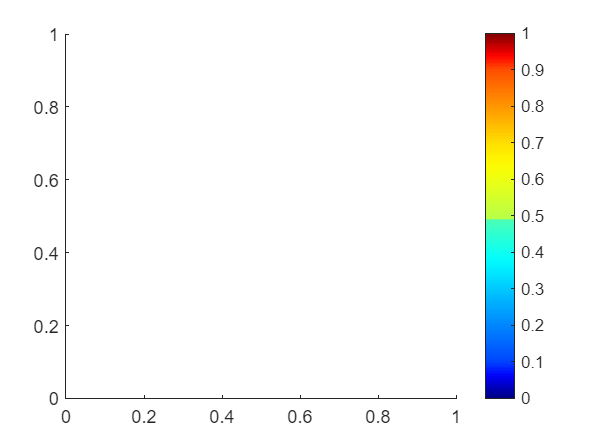

Error using matlab.graphics.illustration.ColorBar/set
Error setting property 'Ticks' of class 'ColorBar':
Value must be a numeric vector whose values increase.

Error in colorbar (line 251)
    set(cbar,pvpairs{:});


% curating data to show smooth volume
dil_organ = imdilate(curr_org, strel('sphere', 3));
  
gt_target = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/" + target + ".nii.gz"));
% gt_target = niftiread(fullfile(data_root + case_nr + "/" + target + ".nii.gz"));

surf_curr = zeros(size(gt_target));
surf_curr(gt_target > 0) = dil_organ(gt_target > 0);
surf_curr = imdilate(surf_curr, strel('sphere', 3));


% output
heatmapConfigT.objectConfig = objectConfigJetV2.objectConfigJetV2;

vol = volshow(surf_curr, heatmapConfigT.objectConfig, 'Parent', vol.Parent);
sceneProps = fields(sceneConfig.sceneConfig);
for prop_idx = 1:length(sceneProps)
    vol.Parent.(sceneProps{prop_idx}) = sceneConfig.sceneConfig.(sceneProps{prop_idx});
end


figure(1)
colormap(heatmapConfigT.objectConfig.Colormap);
c = colorbar('Ticks',[min(curr_org(curr_org>0)) max(curr_org(curr_org>0))],...
         'TickLabels',{string(min_val), string(max_val)});

c.Location = 'northoutside';
c.Label.String = out_metric + ' [Gy]';
axis off
title(curr_org_str)

volshow(gt_target, groundtruthConfig.groundtruthConfig, 'Parent', vol.Parent);
sceneProps = fields(sceneConfig.sceneConfig);
for prop_idx = 1:length(sceneProps)
    vol.Parent.(sceneProps{prop_idx}) = sceneConfig.sceneConfig.(sceneProps{prop_idx});
end


%%% jet changed: blue -> low, red -> high


for oar = oar_list

    gt_oar = niftiread(fullfile(data_root, "ground_truth/" + case_nr + "/" + oar + ".nii.gz"));

    volshow(gt_oar, groundtruthConfig.groundtruthConfig, 'Parent', vol.Parent);
    sceneProps = fields(sceneConfig.sceneConfig);
    for prop_idx = 1:length(sceneProps)
        vol.Parent.(sceneProps{prop_idx}) = sceneConfig.sceneConfig.(sceneProps{prop_idx});
    end
end

% filename = fullfile(repo_root, "results", "animated_" + case_nr + ".avi");
% 
% viewer = vol.Parent;
% hFig = viewer.Parent;
% 
% vol_size = size(gt_target);
% 
% numberOfFrames = 360/2;
% vec = linspace(0,2*pi,numberOfFrames)';
% dist = sqrt(vol_size(1)^2 + vol_size(2)^2 + vol_size(3)^2);
% myPosition = props.Centroid + ([cos(vec) sin(vec) ones(size(vec))]*dist);
% 
% v = VideoWriter(filename,'Uncompressed AVI');
% open(v)
% 
% for idx = 1:length(vec)
%     % Update the current view
%     viewer.CameraPosition = myPosition(idx,:);
%     % Capture the image using the getframe function
%     I = getframe(hFig);
%     % Write the frame to file
%     writeVideo(v,I.cdata)
% end
% close(v)

% clear all;